clc;clear;close all;
%红色
figure;
image=imread("01-刘德华.jpg");
tmp=zeros(size(image));
tmp(:,:,1)=image(:,:,1);
tmp=uint8(tmp);
subplot(2,2,1);
imshow(tmp);
title("红色");
%绿色
image=imread("01-刘德华.jpg");
tmp=zeros(size(image));
tmp(:,:,2)=image(:,:,2);
tmp=uint8(tmp);
subplot(2,2,2);
imshow(tmp);
title("绿色");
%蓝色
image=imread("01-刘德华.jpg");
tmp=zeros(size(image));
tmp(:,:,3)=image(:,:,3);
tmp=uint8(tmp);
subplot(2,2,3);
imshow(tmp);
title("蓝色");


fprintf("R通道最大值为：")

R通道最大值为：

R_max=double(max(max(image(:,:,1))))

R_max = 255

fprintf("G通道最小值为：")

G通道最小值为：

G_min=double(min(min(image(:,:,2))))

G_min = 0

fprintf("B通道均值为：")

B通道均值为：

B_mean=mean(mean(image(:,:,3)))

B_mean = 134.7388

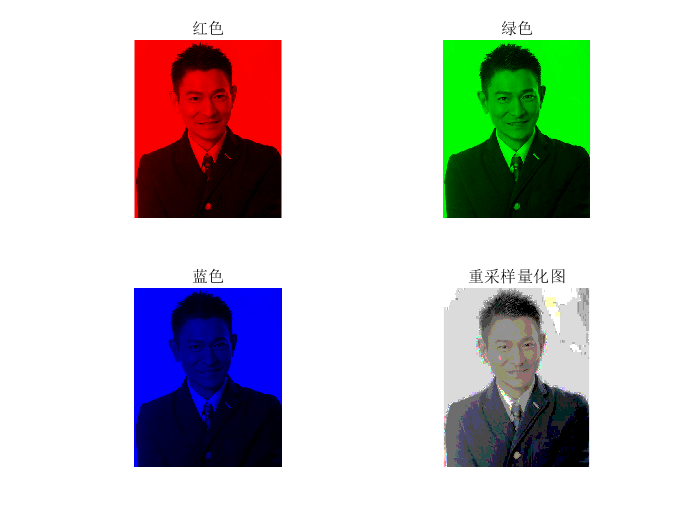




%新建一个图片new
new=zeros(358,441,3);

new=imresize(image,[441,358],'bilinear');
% new(:,:,1)=histeq(new(:,:,1),8);
% new(:,:,2)=histeq(new(:,:,2),8);
% new(:,:,3)=histeq(new(:,:,3),8);
new=histeq(new,8);
subplot(2,2,4);

imshow(new);
title("重采样量化图");


%保存图片
imwrite(new,'result_exp1.jpg'); 











